A = readmatrix("data/GS_56x56.txt");
names = readlines("data\namelist_56x56.txt");
names = names(1:end-1,:);

sum(A,'all')

ans = 1226

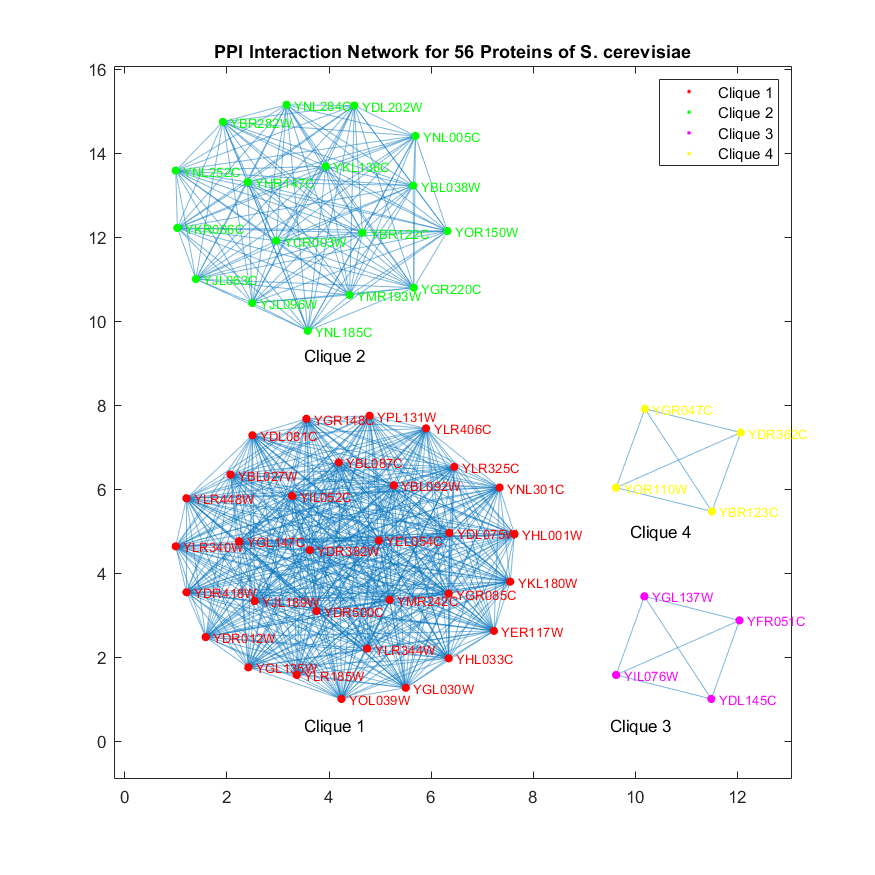

figure;
x0=10;
y0=10;
width=700;
height=700;
set(gcf,'position',[x0,y0,width,height]);
% Plot two lines; they will be invisible because all points are Not-A-Number,
% but they give legend some objects which it can label
plot([NaN NaN], [NaN NaN], '.r')
hold on;
plot([NaN NaN], [NaN NaN], '.g')
plot([NaN NaN], [NaN NaN], '.m')
plot([NaN NaN], [NaN NaN], '.y')

set(gca, 'ColorOrderIndex', 1)

g = graph(A,names);
h = plot(g);
layout(h,'force')
title("PPI Interaction Network for 56 Proteins of S. cerevisiae")
highlight(h,names(C(:,1)==1),"NodeColor","red","NodeLabelColor","red")
highlight(h,names(C(:,2)==1),"NodeColor","green","NodeLabelColor","green")
highlight(h,names(C(:,3)==1),"NodeColor","magenta","NodeLabelColor","magenta")
highlight(h,names(C(:,4)==1),"NodeColor","yellow","NodeLabelColor","yellow")
legend(["Clique 1" , "Clique 2","Clique 3" , "Clique 4"])
text(3.5,0.4,"Clique 1")
text(3.5,9.2,"Clique 2")
text(9.5,0.4,"Clique 3")
text(9.9,5,"Clique 4")
saveas(gcf,'images/allcliques_gs.png')
hold off


idx = C(:,1)==1;

clique1_names = names(idx);

c1 = graph(A(idx,idx),clique1_names);
h1 = plot(c1)

h1 =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {1×31 cell}
     EdgeLabel: {}
         XData: [3.0976 -2.6423 -0.6772 3.4264 -0.5981 1.4907 -2.1026 -0.2027 0.8460 -0.4338 -2.9990 0.2882 -1.9486 0.8177 1.7190 1.8997 0.7203 2.5233 2.1963 -3.1256 -1.4439 -1.0803 2.1225 -2.2675 -3.2677 1.5265 3.0036 0.4192 -1.7331 -1.3393 -0.2354]
         YData: [1.3469 -1.5922 2.0257 -0.2285 0.4255 -3.0103 -2.5674 3.3459 -0.1863 -2.3259 1.4421 -3.2781 -0.1452 -1.9155 2.9123 -0.8743 2.7989 0.2949 1.9977 0.3616 -1.3466 -3.1688 -2.1431 2.3465 -0.7352 0.9823 -1.4630 1.4906 1.1830 3.0022 -0.9759]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]

  Show 

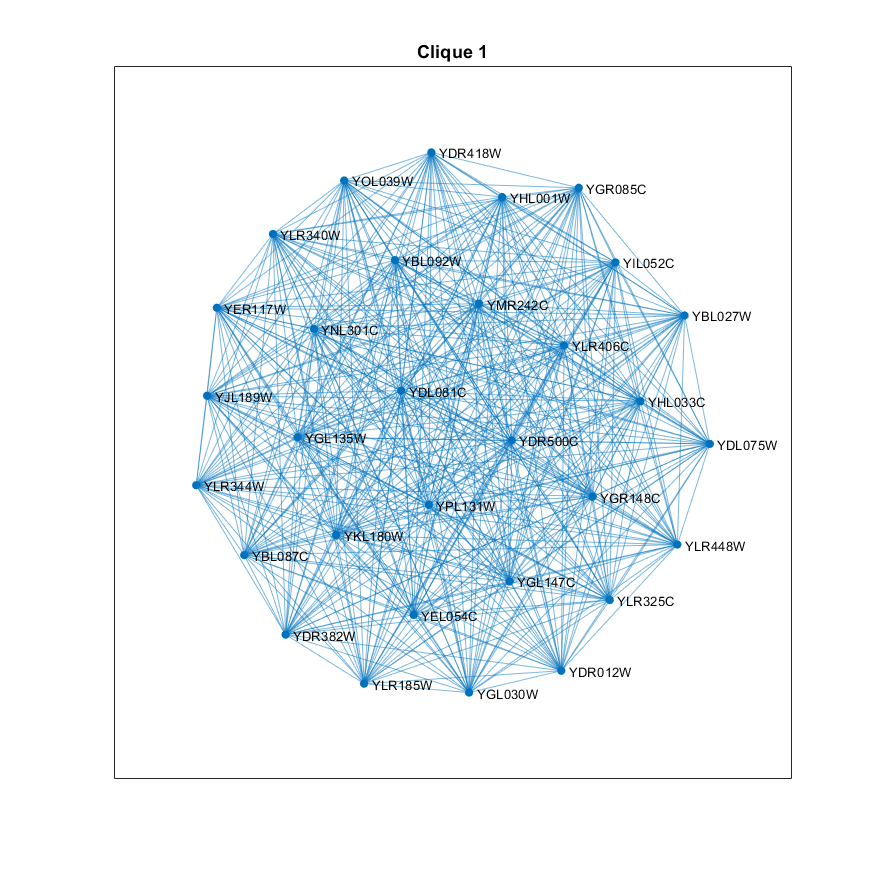

title("Clique 1")
saveas(gcf,'images/clique1.png')

ans = 56×1 table
       Name    
    ___________

    {'YBL027W'}
    {'YBL038W'}
    {'YBL087C'}
    {'YBL092W'}
    {'YBR122C'}
    {'YBR123C'}
    {'YBR282W'}
    {'YCR003W'}
    {'YDL075W'}
    {'YDL081C'}
    {'YDL145C'}
    {'YDL202W'}
    {'YDR012W'}
    {'YDR362C'}
    {'YDR382W'}
    {'YDR418W'}


Finding Maximal Cliques from Gold Standard Dataset. 

x = zeros(56,1);
x1 = zeros(56,1);
x1(1)=1;
C = [];


C =

     []



for i=1:5
    
        x1 = findMaximalClique(A,x,"allow");
        if sum(x1)==0
             break
         end
         x = x1+x;
         sum(x1)
         C = [C x1];
         
   
end

ans = "allow"

Solving problem using intlinprog.
LP:                Optimal objective value is -31.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



ans = 31

ans = "allow"

Solving problem using intlinprog.
LP:                Optimal objective value is -30.760000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



ans = 17

ans = "allow"

Solving problem using intlinprog.
LP:                Optimal objective value is -30.250000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



ans = 4

ans = "allow"

Solving problem using intlinprog.
LP:                Optimal objective value is -29.500000.                                           

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is -4.000000.                                                        
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



ans = 4

ans = "allow"

Solving problem using intlinprog.

No feasible solution found.

Intlinprog stopped because no point satisfies the constraints.



sum(C)

ans =     31    17     4     4


rng(1)
A = readmatrix("data/GS_56x56.txt");
a = rand(56);
a = a'*a;
a = (a>11) +diag(ones(56,1));
A = A.*a;
x =  findMaximalClique(A)

Solving problem using intlinprog.
LP:                Optimal objective value is -28.000000.                                           

Heuristics:        Found 2 solutions using ZI round.                                                
                   Upper bound is -27.000000.                                                       
                   Relative gap is 0.00%.                                                          

Cut Generation:    Applied 1 clique cut.                                                            
                   Lower bound is -27.000000.                                                       
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default v

x =      0
     0
     0
     1
     0
     0
     0
     0
     1
     1


sum(x)

ans = 27

tic
sol = invNearClique(A,27 ,31-27)

Solving problem using intlinprog.
LP:                Optimal objective value is 11.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



sol = struct with fields:
    C: [56×1 double]
    V: [941×1 double]
    W: 11


toc

Elapsed time is 0.050639 seconds.


sum(sol.C)

ans = 31

sum(sol.C==C(:,1))

ans = 56


sum(sol.V)

ans = 11

num_edges = [];
for i=1:20
    sol = invNearClique(A,27 ,i);
    num_edges(i)=sum(sol.V)
end

Solving problem using intlinprog.
LP:                Optimal objective value is 0.000000.                                             

Cut Generation:    Applied 12 zero-half cuts,                                                       
                   and 1 Gomory cut.                                                                
                   Lower bound is 1.000000.                                                         
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).


num_edges = 1

Solving problem using intlinprog.
LP:                Optimal objective value is 3.000000.                                             


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3


Solving problem using intlinprog.
LP:                Optimal objective value is 6.000000.                                             


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6


Solving problem using intlinprog.
LP:                Optimal objective value is 11.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11


Solving problem using intlinprog.
LP:                Optimal objective value is 42.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42


Solving problem using intlinprog.
LP:                Optimal objective value is 73.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73


Solving problem using intlinprog.
LP:                Optimal objective value is 104.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104


Solving problem using intlinprog.
LP:                Optimal objective value is 135.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135


Solving problem using intlinprog.
LP:                Optimal objective value is 166.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166


Solving problem using intlinprog.
LP:                Optimal objective value is 197.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197


Solving problem using intlinprog.
LP:                Optimal objective value is 228.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197   228


Solving problem using intlinprog.
LP:                Optimal objective value is 259.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197   228   259


Solving problem using intlinprog.
LP:                Optimal objective value is 290.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197   228   259   290


Solving problem using intlinprog.
LP:                Optimal objective value is 321.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197   228   259   290   321


Solving problem using intlinprog.
LP:                Optimal objective value is 352.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197   228   259   290   321   352


Solving problem using intlinprog.
LP:                Optimal objective value is 383.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197   228   259   290   321   352   383


Solving problem using intlinprog.
LP:                Optimal objective value is 414.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197   228   259   290   321   352   383   414


Solving problem using intlinprog.
LP:                Optimal objective value is 445.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197   228   259   290   321   352   383   414   445


Solving problem using intlinprog.
LP:                Optimal objective value is 476.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197   228   259   290   321   352   383   414   445   476


Solving problem using intlinprog.
LP:                Optimal objective value is 508.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



num_edges =      1     3     6    11    42    73   104   135   166   197   228   259   290   321   352   383   414   445   476   508


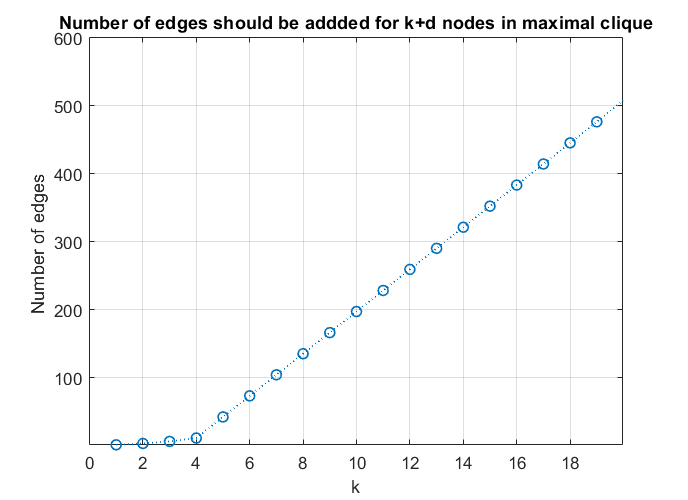

figure(1);
fig1_comps.fig = gcf;

fig1_comps.p1 =plot(1:20,num_edges,':o',"LineWidth",1);

    title(['Number of edges should be addded for k+d nodes in maximal clique' ]);
xlabel('k');
ylabel('Number of edges ');
grid on
saveas(gcf,'images/kvsnedges.png')

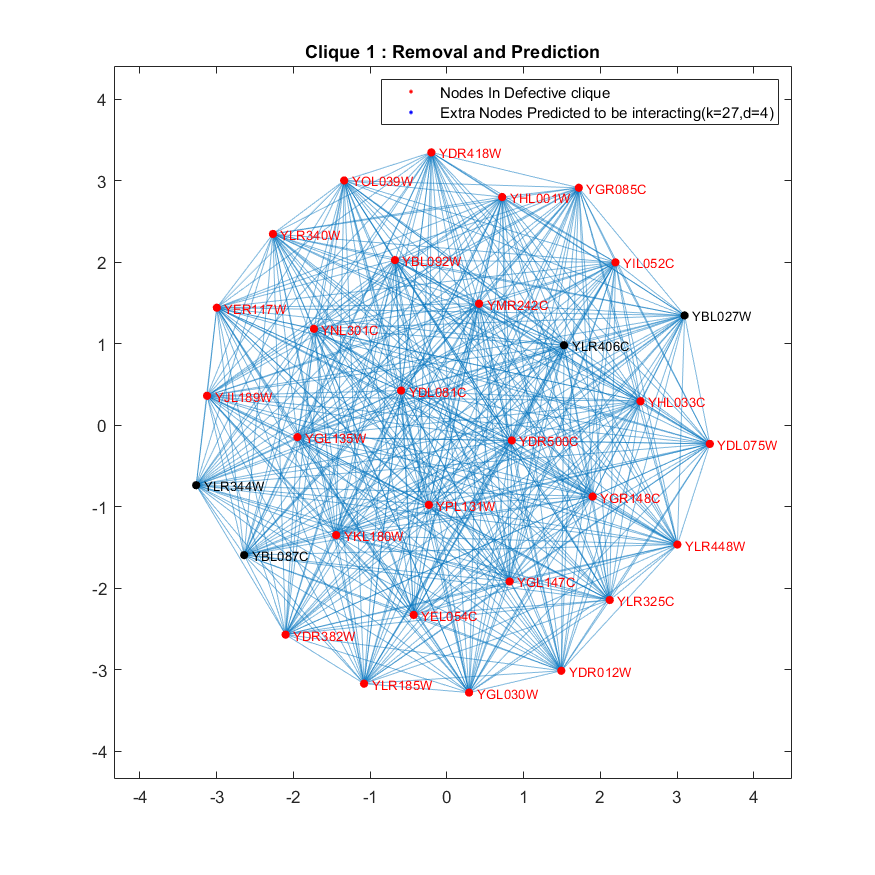

plot([NaN NaN], [NaN NaN], '.r')
hold on
plot([NaN NaN], [NaN NaN], '.b',"LineWidth",2)
set(gca, 'ColorOrderIndex', 1)
g2 = graph(A(idx,idx),names(idx));
h2 = plot(c1);
highlight(h2,names(x==1),"NodeColor","red","NodeLabelColor","red")
highlight(h2,names((sol.C - x)==1),"NodeColor","black","NodeLabelColor","black")
legend(["Nodes In Defective clique","Extra Nodes Predicted to be interacting(k=27,d=4)"])
title("Clique 1 : Removal and Prediction")
saveas(gcf,'images/removalandpred.png')
hold off

[sol,edges] = invNearClique(A,27 ,31-27+10);

Solving problem using intlinprog.
LP:                Optimal objective value is 321.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon
variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).



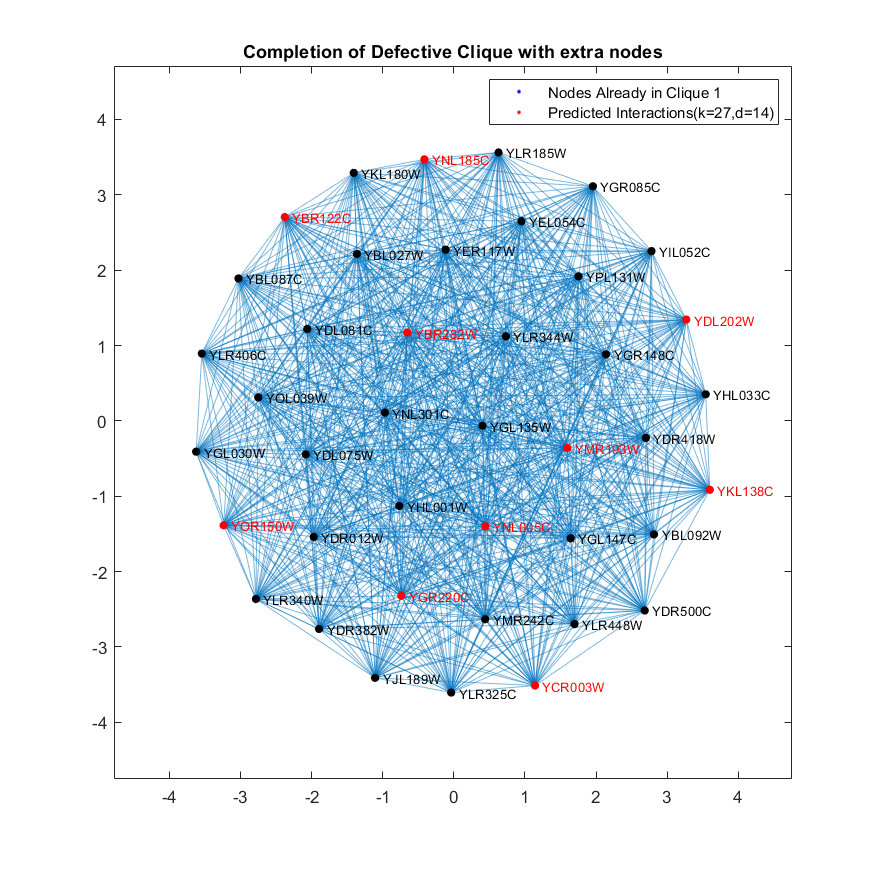


A_ = A;
A_(edges(:,1),edges(:,2))=1;
sum(sol.C);
idx = sol.C==1;

plot([NaN NaN], [NaN NaN], '.b')
hold on
plot([NaN NaN], [NaN NaN], '.r')
set(gca, 'ColorOrderIndex', 1)
g3 = graph(A_(idx,idx),names(idx),"lower","omitselfloops");
h3 = plot(g3);
highlight(h3,names(C(:,1)==1),"NodeColor","black","NodeLabelColor","black")
highlight(h3,names((sol.C - C(:,1) )==1),"NodeColor","red","NodeLabelColor","red")
title("Completion of Defective Clique with extra nodes")
legend(["Nodes Already in Clique 1","Predicted Interactions(k=27,d=14)"])
saveas(gcf,'images/extrapred.png')
hold off